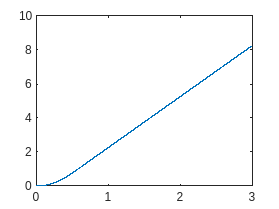

clc; clear all; close all;

R = 20; % Ohm
L = 4; % H
C = 2.5*10^-3; % F

U_min = 0; % V
U_max = 12; % V
tr = 0.5; % s

t = 0; % s
simTime = 3; % s
dt = 10^-5; % s
idx = 1;

iL = 0; % A

while(t <= simTime)
    % Calculation

    if(t < tr)
        U = t/tr*U_max;
    else
        U = U_max;
    end
    
    uB = U-iL*R;
    uCDot = 1/C * iL;
    iLDot = 1/L*(uB-uC);

    % Logging
    t_plt(idx) = t;
    iL_plt(idx) = iL;

    % Time integration
    iL = iL + iLDot*dt;
    uC 

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, iL_plt)